% Read in N x N x Time Slice Adj Array
filenames = dir("/mnt/chrastil/lab/users/rob/projects/DynConn/3DArrays/sub-*Coh_2mm_3Darray.mat");
rois = 414;

% Subject 33
i = 19;

sub_label = split(filenames(i).name, "_");
sub_label = split(sub_label(1), "-");
sub_labels(i) = sub_label(2);
disp(filenames(i).name);

sub-033_Ex_HOsubcort+Schaefer400Coh_2mm_3Darray.mat



arr_dict = load(fullfile(filenames(i).folder, filenames(i).name));

array3D_ex1 = permute(arr_dict.scan_1, [3 2 1]);
array3D_ex2 = permute(arr_dict.scan_2, [3 2 1]);

array3D = cat(3, array3D_ex1, array3D_ex2);
A = num2cell(array3D, [1 2]);
[X, N, T] = size(array3D)

X = 414

N = 414

T = 10

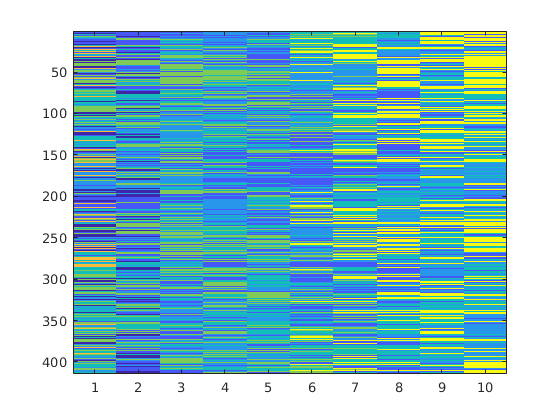

% Turn Adj Array into Modularity Array
[B, mm] = multiord(A, 1, 1);

PP = @(S) postprocess_ordinal_multilayer(S,T);

% Perform Optimization with Generalized Louvain Method
[S,Q, n_it] = iterated_genlouvain(B, 10000, 0, 1, 'moverandw', [], PP);

Q = Q/mm;
S = reshape(S,N,T);

imagesc(S);